outdir = fullfile(pwd, 'output', 'jobs', 'allrisk_base_small');  % <-- change as needed

%% 1. Load job config and chunk list
job_config = yaml.loadFile(fullfile(outdir, 'job_config.yaml'));
sim_periods = job_config.sim_periods;
num_simulations = job_config.num_simulations;

rawdir = fullfile(outdir, 'raw');
chunk_dirs = dir(fullfile(rawdir, 'chunk_*'));
chunk_dirs = chunk_dirs([chunk_dirs.isdir]);
[~, sort_idx] = sort(cellfun(@(x) sscanf(x, 'chunk_%d'), {chunk_dirs.name}));
chunk_dirs = chunk_dirs(sort_idx);

%% 2. Load base and pandemic tables (inspection columns)
% Base: severity, duration, response flag. Pandemic: ex_post_severity, rd_state if present.
base_vars_wanted = {'sim_num', 'yr_start', 'eff_severity', 'response_outbreak', 'is_false', ...
    'natural_dur', 'actual_dur', 'severity', 'intensity', 'pathogen'};
pandemic_vars_wanted = {'sim_num', 'yr_start', 'ex_post_severity', 'actual_dur', 'rd_state'};

all_base = {};
all_pandemic = {};
for i = 1:length(chunk_dirs)
    chunk_dir = fullfile(rawdir, chunk_dirs(i).name);
    base_path = fullfile(chunk_dir, 'base_simulation_table.mat');
    if isfile(base_path)
        S = load(base_path, 'base_simulation_table');
        base_t = S.base_simulation_table;
        base_vars = base_vars_wanted(ismember(base_vars_wanted, base_t.Properties.VariableNames));
        base_t = base_t(:, base_vars);
        base_t = base_t(~base_t.is_false & ~isnan(base_t.yr_start), :);
        if ismember('is_false', base_t.Properties.VariableNames)
            base_t.is_false = [];
        end
        all_base{end+1} = base_t;
    end
    pandemic_path = fullfile(chunk_dir, 'baseline_pandemic_table.mat');
    if isfile(pandemic_path)
        S = load(pandemic_path, 'pandemic_table');
        pan_t = S.pandemic_table;
        pan_vars = pandemic_vars_wanted(ismember(pandemic_vars_wanted, pan_t.Properties.VariableNames));
        pan_t = pan_t(:, pan_vars);
        pan_t = pan_t(~isnan(pan_t.yr_start), :);
        all_pandemic{end+1} = pan_t;
    end
end

if isempty(all_base)
    error('No base_simulation_table.mat found in any chunk.');
end
if isempty(all_pandemic)
    error('No baseline_pandemic_table.mat found in any chunk.');
end
base_merged = vertcat(all_base{:});
pandemic_merged = vertcat(all_pandemic{:});

%% 3. Merge on (sim_num, yr_start) and build inspection table
pandemic_keys = pandemic_merged(:, {'sim_num', 'yr_start', 'ex_post_severity'});
merged = outerjoin(base_merged, pandemic_keys, 'Keys', {'sim_num', 'yr_start'}, 'Type', 'left', 'MergeKeys', true);

% Ex-post severity: from pandemic when present, else same as eff_severity (no response)
missing_post = isnan(merged.ex_post_severity);

merged.ex_post_severity(missing_post) = merged.eff_severity(missing_post);


% Duration for display (actual_dur if present, else natural_dur)
if ismember('actual_dur', merged.Properties.VariableNames)
    duration = merged.actual_dur;
elseif ismember('natural_dur', merged.Properties.VariableNames)
    duration = merged.natural_dur;
else
    duration = nan(height(merged), 1);
end

% Vaccine reduced severity (ex_post < eff when response outbreak)
vaccine_reduced = merged.eff_severity > merged.ex_post_severity;
vaccine_reduced(missing_post) = false;  % no vaccine for non-response outbreaks

% Keep one set of key names for table (handle MergeKeys suffixes)
key_sn = merged.Properties.VariableNames{find(contains(merged.Properties.VariableNames, 'sim_num'), 1)};
key_yr = merged.Properties.VariableNames{find(contains(merged.Properties.VariableNames, 'yr_start'), 1)};

inspect = table(merged.(key_sn), merged.(key_yr), merged.eff_severity, merged.ex_post_severity, ...
    duration, vaccine_reduced, ...
    'VariableNames', {'sim_num', 'yr_start', 'eff_severity', 'ex_post_severity', 'duration', 'vaccine_reduced_severity'});

if ismember('response_outbreak', merged.Properties.VariableNames)
    inspect.response_outbreak = merged.response_outbreak;
end
if ismember('pathogen', merged.Properties.VariableNames)
    inspect.pathogen = merged.pathogen;
end
if ismember('rd_state', merged.Properties.VariableNames)
    inspect.rd_state = merged.rd_state;
end

% Sort by severity (desc) then sim_num, yr_start for easy inspection
inspect = sortrows(inspect, {'eff_severity', 'sim_num', 'yr_start'}, {'ascend', 'ascend', 'ascend'});
inspect2 = sortrows(inspect, {'ex_post_severity', 'sim_num', 'yr_start'}, {'ascend', 'ascend', 'ascend'});


%% 4. Display table (inspect in Variable Editor or command window)
disp('Inspection table (first 20 rows):');

Inspection table (first 20 rows):


disp(inspect(1:min(20, height(inspect)), :));

    sim_num    yr_start    eff_severity    ex_post_severity    duration    vaccine_reduced_severity    response_outbreak      pathogen   
    _______    ________    ____________    ________________    ________    ________________________    _________________    _____________

     20080        20          0.001             0.001             1                 false                    false          zika         
     18712         3          0.001             0.001             1                 false                    false          flu          
      4586       200          0.001             0.001             1                 false                    false          flu          
      5403        22          0.001  

% Optional: openvar('inspect');   % open in Variable Editor
% Optional: writetable(inspect, fullfile(outdir, 'inspect_exceedance.csv'));   % export to CSV

%% 5. Exceedance curves (direct, same logic as compare_exceedances)
ante_severity_matrix = zeros(num_simulations, sim_periods);
post_severity_matrix = zeros(num_simulations, sim_periods);
idx = sub2ind(size(ante_severity_matrix), inspect.sim_num, inspect.yr_start);
ante_severity_matrix(idx) = inspect.eff_severity;
post_severity_matrix(idx) = inspect.ex_post_severity;

ante_sev_all = ante_severity_matrix(:);
post_sev_all = post_severity_matrix(:);
min_grid = min(ante_sev_all(ante_sev_all > 0));
max_grid = max(ante_sev_all(isfinite(ante_sev_all)));
num_grid_points = 1000;
direct_edges = [0; logspace(log10(min_grid), log10(max_grid), num_grid_points - 1)'];
ante_direct = (numel(ante_sev_all) - histcounts(ante_sev_all, direct_edges, 'Normalization', 'cumcount')) ./ (numel(ante_sev_all) + 1);
post_direct = (numel(post_sev_all) - histcounts(post_sev_all, direct_edges, 'Normalization', 'cumcount')) ./ (numel(post_sev_all) + 1);
x_ribbon_direct = direct_edges(2:end)';

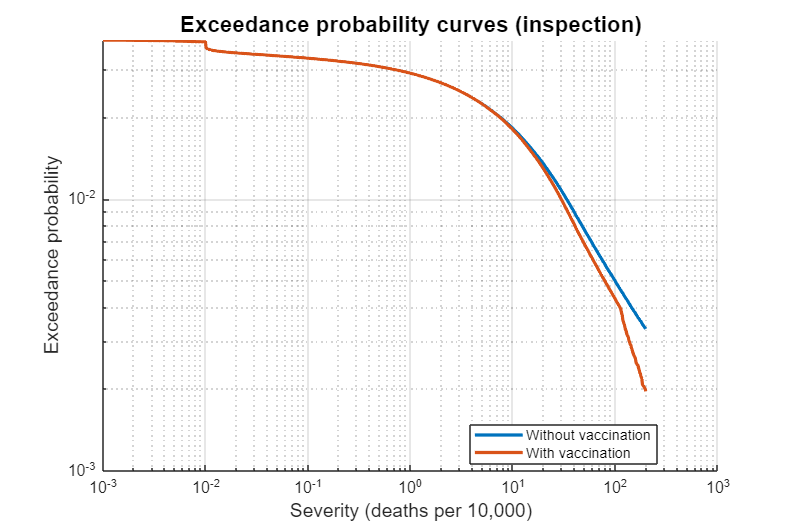


%% 6. Plot exceedance curves
figure('Position', [100 100 900 600]); hold on;
plot(x_ribbon_direct, ante_direct, 'LineWidth', 2, 'Color', [0 0.4470 0.7410], 'DisplayName', 'Without vaccination');
plot(x_ribbon_direct, post_direct, 'LineWidth', 2, 'Color', [0.8500 0.3250 0.0980], 'DisplayName', 'With vaccination');
set(gca, 'XScale', 'log', 'YScale', 'log');
grid on; box off;
xlabel('Severity (deaths per 10,000)', 'FontSize', 12);
ylabel('Exceedance probability', 'FontSize', 12);
title('Exceedance probability curves (inspection)', 'FontSize', 14);
legend('Location', 'best');

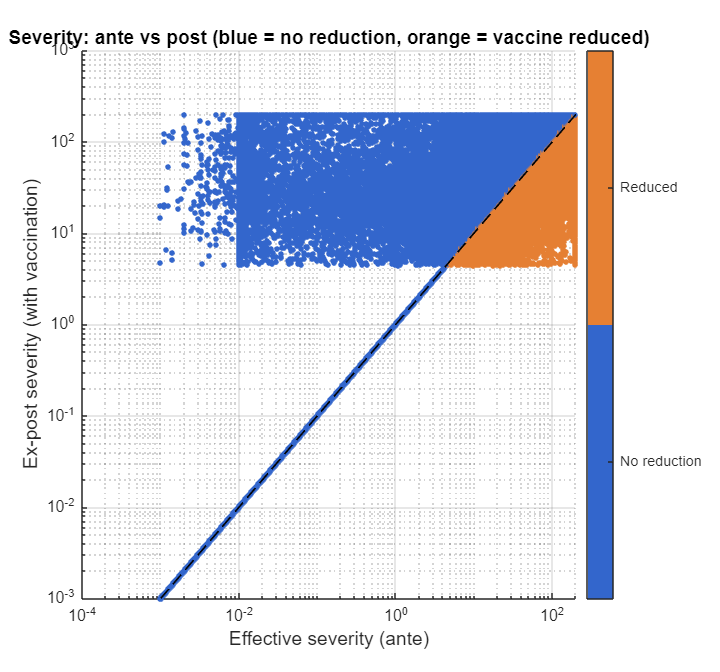


% Optional: scatter of eff vs ex_post colored by vaccine_reduced_severity
figure('Position', [120 120 600 560]); hold on;
col = double(inspect.vaccine_reduced_severity);
scatter(inspect.eff_severity, inspect.ex_post_severity, 12, col, 'filled');
cmap = [0.2 0.4 0.8; 0.9 0.5 0.2];  % blue = no reduction, orange = reduced
colormap(gca, cmap);
caxis([0 1]);
plot([min(inspect.eff_severity), max(inspect.eff_severity)], [min(inspect.eff_severity), max(inspect.eff_severity)], 'k--', 'LineWidth', 1);
set(gca, 'XScale', 'log', 'YScale', 'log');
xlabel('Effective severity (ante)', 'FontSize', 12);
ylabel('Ex-post severity (with vaccination)', 'FontSize', 12);
title('Severity: ante vs post (blue = no reduction, orange = vaccine reduced)', 'FontSize', 12);
colorbar('Ticks', [0.25 0.75], 'TickLabels', {'No reduction', 'Reduced'});
grid on; box off;


fprintf('Inspection table has %d rows. Variable ''inspect'' is in workspace for export or more filtering.\n', height(inspect));

Inspection table has 464946 rows. Variable 'inspect' is in workspace for export or more filtering.
